# Machine Learning with MATLAB 

Digital Twin & Automation

# Logistic Regression

## Binary linear classifier

`Method 1:`fitclinear()

- For two-class (binary) learning with **high-dimensional**, full or sparse predictor data. 

`Method 2:`fitglm()

- For low- through medium-dimensional predictor data sets, see [Alternatives for Lower-Dimensional Data](https://www.mathworks.com/help/releases/R2021b/stats/fitclinear.html#mw_d1b0a02e-0dfa-4c0e-bb4d-e6859309ec45)

## **Example 1: Logistic Regression**

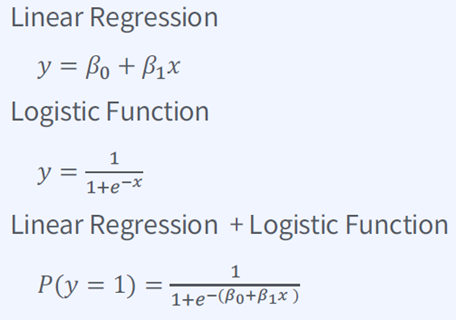

**Data Acquisition** 

clear
load fisheriris
X = meas(:,1:2);            % Use two features (x1, x2) for fitting
sp = categorical(species);
Ystat=sp=='setosa';         % Binary classfication:  setosa vs no-setosa
%sp가 setosa일때 만 1
%bias = beta0

**Classification: **Logistic Regression 

Mdl = fitclinear(X,Ystat,'Learner','logistic')

Mdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'logit'
              Beta: [2×1 double]
              Bias: 8.3233
            Lambda: 0.0067
           Learner: 'logistic'


  Properties, Methods


**Plot**  Logistic Regression of Train data:  z vs Logistic Function

- z= b0+b1X1+b2X2

- y=1/(1+exp(-z))

% Plot z vs Y=sigmoid(z)
% z = b0 + b1*x1 + b2*x2
z=Mdl.Bias+X*Mdl.Beta;

%%% YOUR CODE GOES HERE
% y=1/(1+exp(-z))
Y= 1./ ( 1 + exp(-z));  % Logistic function


Y1indx=find(sp=='setosa')

Y1indx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Y0indx=find(sp~='setosa')

Y0indx =     51
    52
    53
    54
    55
    56
    57
    58
    59
    60


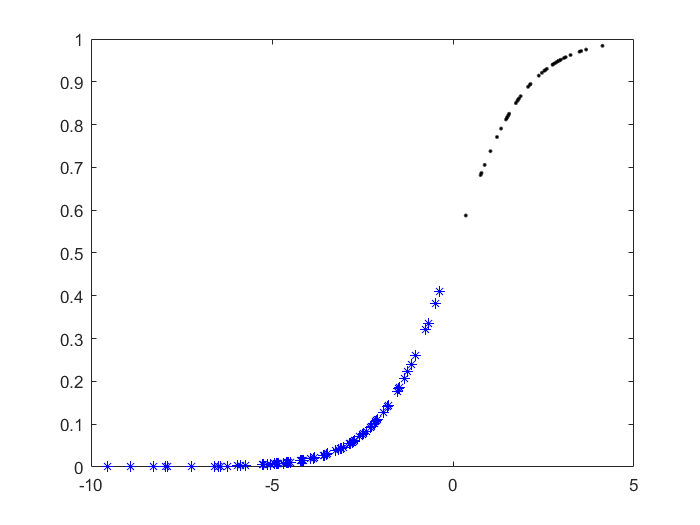



figure
plot(z(Y1indx),Y(Y1indx),'k.')
hold on
plot(z(Y0indx),Y(Y0indx),'b*')
hold off

#### Cross-validation (k-fold)

Construct a cross-validated classifier from the model.

cvMdl = fitclinear(X,Ystat,'Learner','logistic', 'KFold',5)

cvMdl =   ClassificationPartitionedLinear
    CrossValidatedModel: 'Linear'
           ResponseName: 'Y'
        NumObservations: 150
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


mdl1 = cvMdl.Trained{1}

mdl1 =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'logit'
              Beta: [2×1 double]
              Bias: 7.9847
            Lambda: 0.0083
           Learner: 'logistic'


  Properties, Methods


%1 빼고 학습
%2 빼고 학습
%5까지하고 평균 이게 cross validation

Examine the cross-validation loss, which is the average loss of each cross-validation model when predicting on data that is not used for training.

kloss = kfoldLoss(cvMdl)

kloss = 0

**Test **  

% an average flower feature values
flwr = mean(X); 
flwr2 = mean(X(1:10,:)); 
Xtest=flwr2;

% Convert TestData as Logistic Function
ztest=mdl1.Bias+Xtest*mdl1.Beta;

%%% YOUR CODE GOES HERE
Ytest=1./ ( 1 + exp(-ztest));

flwrClass = predict(mdl1,Xtest)

flwrClass = logical
   1


# Exercise

## Exercise 1:  CWRU dataset

Apply logistic regression to classifiy   outer or  inner bearing fault  

### Dataset 

- Given dataset contains many features extracted from CWRU dataset

- For binary class:  Outer and Inner Race Fault

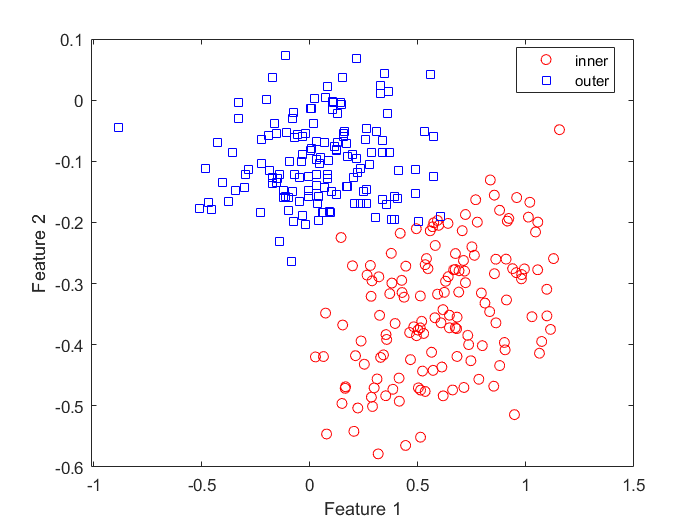

clear

% Class 'Inner', 'Outer'
load("../4weeks_machine_learning/CWRU_features/example_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));

Ytrain = class_cwru_train;       % fault class
classKeep = ~strcmp(Ytrain,'normal');  % eliminate normal class
X = Xtrain(classKeep,:);
Y = Ytrain(classKeep);
sp = categorical(Y);

% Plot features 
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

**Classify using Logistic Regression and Analyze **

% Your code goes here
% Your code goes here
Ystat= sp == 'inner'; %sp가 1일때 만 1 

Mdl = fitclinear(X,Ystat,'Learner','logistic')

Mdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'logit'
              Beta: [2×1 double]
              Bias: -2.7284
            Lambda: 0.0035
           Learner: 'logistic'


  Properties, Methods


z=Mdl.Bias+X*Mdl.Beta;

Y= 1./ ( 1 + exp(-z));  % Logistic function
Y1indx=find(sp=='inner')

Y1indx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Y0indx=find(sp ~='inner')

Y0indx =    145
   146
   147
   148
   149
   150
   151
   152
   153
   154


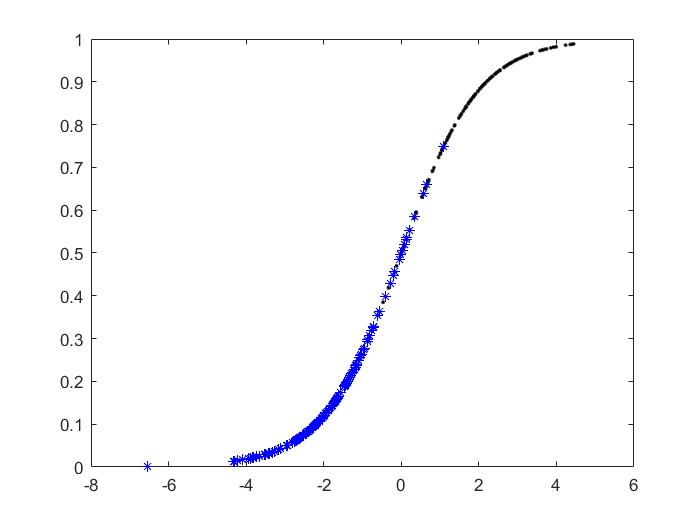


figure
plot(z(Y1indx),Y(Y1indx),'k.')
hold on
plot(z(Y0indx),Y(Y0indx),'b*')
hold off

cvMdl = fitclinear(X,Ystat,'Learner','logistic', 'KFold',10)

cvMdl =   ClassificationPartitionedLinear
    CrossValidatedModel: 'Linear'
           ResponseName: 'Y'
        NumObservations: 288
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


kloss = kfoldLoss(cvMdl)

kloss = 0.0556

**Predict  test data and Analyze**

% Class 'Inner', 'Outer'
load("../4weeks_machine_learning/CWRU_features/example_test.mat");

% Your code goes here
% Your code goes here
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));

Ytest = class_cwru_test;       % fault class
classKeep_test = ~strcmp(Ytest,'normal');  % eliminate normal class
X_test = Xtest(classKeep_test,:);

ztest=Mdl.Bias+Xtest*Mdl.Beta;

Ytest=1./ ( 1 + exp(-ztest));

dataClass = predict(Mdl,X_test)

dataClass = 72×1 logical 배열
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


## Exercise 2

**Use gradient descent to obtain optimal parameters of Logistic Regression**

**Cost function**

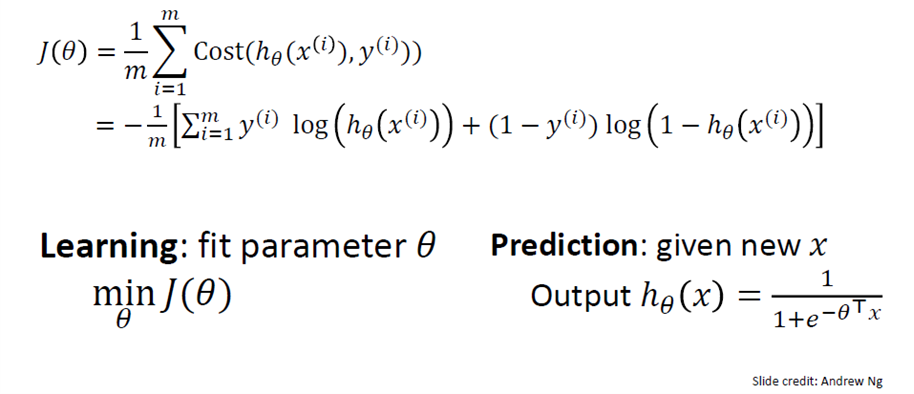

**Gradient Descent**

 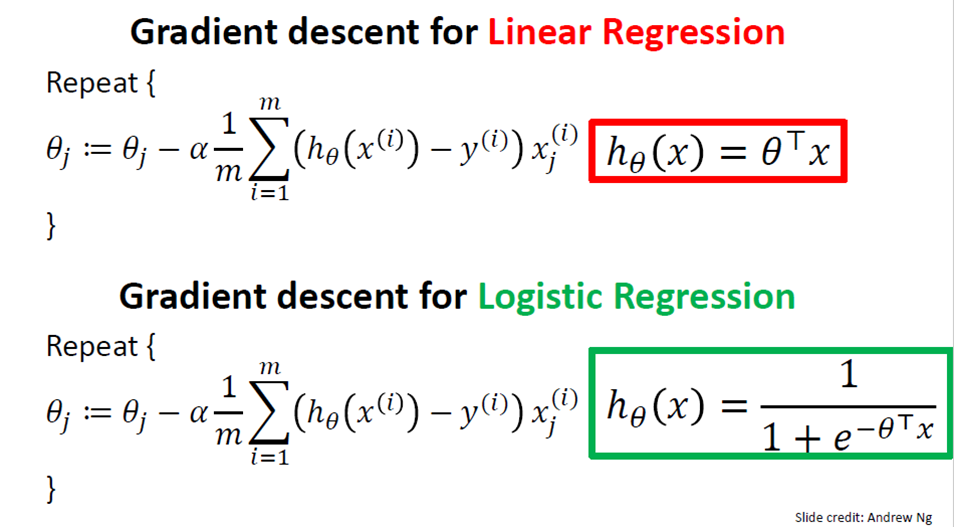

% Your code goes here
% Your code goes here
% Your code goes here

clear

% Class 'Inner', 'Outer'
load("../4weeks_machine_learning/CWRU_features/example_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));
Xtrain(:, 3) = 1;
Ytrain = class_cwru_train;       % fault class
classKeep = ~strcmp(Ytrain,'normal');  % eliminate normal class
X = Xtrain(classKeep,:);
Y = Ytrain(classKeep);
sp = categorical(Y);
Ystat= sp == 'inner'; %sp가 1일때 만 1 
% Plot features 
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

lamda=0.1  % learning rate

lamda = 0.1000

t0=0.5;
t1=0.5;
t2=0.5;
e=1;
itrN=2000;
k=0

k = 0

m =length(Ystat);


while(e>0.001 && k<itrN)
    
    theta = [t2,t1,t0];
    theta = theta';
    h = 1./ (1 + exp(-X*theta));
    %h = sigmoid(X*theta);
    J = (1/m)*sum((-Ystat).*log(h)-(1-Ystat).*log(1-h));
    grad = (1/m).*(X'*(h-Ystat));
     
    t2_new = t2 - lamda * grad(1,1);
    t1_new = t1 - lamda * grad(2,1); 
    t0_new = t0 - lamda * grad(3,1); 

    e = (abs((t0_new - t0)) + abs((t1_new - t1)) + abs((t2_new - t2))) / 3;
  
    t2=t2_new;
    t1=t1_new;
    t0=t0_new;
    
    k=k+1;
end

ypred =t2*X(1,:) + t1*X(2,:) + t0;
